# Lab 6 - Zakary Steenhoek - MAT 275 Lab

Forced Equations and Resonance

# Exercise 1

### Part (a)

Period of the forced oscillation: Period = 1/frequency, omega = 2pi*frequency. 

Omega = 3.4; Frequency = 0.541127.

**Period = 1.848**

Numerical value of the angle $\alpha$: **37.4437 degrees**, from (4) w0>w

### Part (b)

type LAB06ex1_b.m

clear; clc; %this deletes all variables 
omega0 = 4; c = 1; omega = 3.4;
if omega0 > omega
    alpha = atan((c*omega)/(omega0.^2-omega.^2));
else
    alpha = pi + atan((c*omega)/(omega0.^2-omega.^2));
end
param = [omega0,c,omega]; 
t0 = 0; y0 = 0; v0 = 0; Y0 = [y0;v0]; tf = 60;
options = odeset('AbsTol',1e-10,'relTol',1e-10); 
[t,Y] = ode45(@f,[t0,tf],Y0,options,param);  
t1 = 25; i = find(t>t1);
C = (max(Y(i,1))-min(Y(i,1)))/2;
y = Y(:,1)-C*cos(omega*t-alpha); v = Y(:,2);
figure(1); clf;
plot(t,y,'b-'); ylabel('y'); grid on; 
disp(['computed amplitude of forced oscillation = ', num2str(C)]);
Ctheory = 1/sqrt((omega0^2-omega^2)^2+(c*omega)^2); 
disp(['theoretical amplitude = ', num2str(Ctheory)]);
%----------------------------------------------------------------
function dYdt = f(t,Y,param) 
y = Y(1); v = Y(2); 
omega0 = param(1); c = param(2); omega = param(3);
dYdt = [ v ; cos(omega*t)-omega0^2*y-c*v ];
end


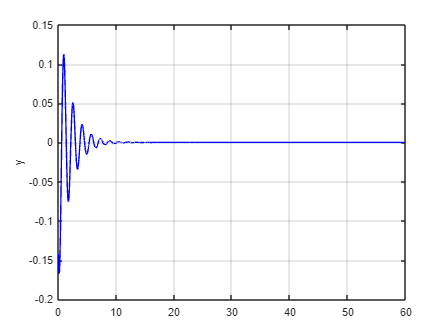

computed amplitude of forced oscillation = 0.17882
theoretical amplitude = 0.17882


LAB06ex1_b

Does it look like an  exponentially decreasing oscillation? Why or why not?

    This does look like an exponentially decreasing oscillation because amplitude slowly goes to zero as energy is bled from the system. This happens because when we subtract the quantity from y, it effectivley negates the forcing function keeping the system in motion.

# Exercise 2

### Part (a)

type LAB06ex2.m

clear; clc; %this deletes all variables 
omega0 = 4; c = 1;
OMEGA =2:0.01:5;
C = zeros(size(OMEGA));
Ctheory = zeros(size(OMEGA)); 
t0 = 0; y0 = 0; v0 = 0; Y0 = [y0;v0]; tf =60; t1 = 25;
for k = 1:length(OMEGA)
   omega = OMEGA(k);
   param = [omega0,c,omega];
   [t,Y] = ode45(@f,[t0,tf],Y0,[],param); 
   i = find(t>t1); 
   C(k) = (max(Y(i,1))-min(Y(i,1)))/2; 
   Ctheory(k) = 1/sqrt((omega0^2-omega^2)^2+(c*omega)^2); 
end 
figure(4); clf; 
plot(OMEGA, C, OMEGA, Ctheory); grid on; % FILL-IN to plot C and Ctheory as a function of OMEGA 
xlabel('\omega'); ylabel('C'); 
legend('computed numerically','theoretical') 
%---------------------------------------------------------
function dYdt = f(t,Y,param) 
y = Y(1); v = Y(2); 
omega0 = param(1); c = param(2); omega = param(3);
dYdt = [ v ; cos(omega*t)-omega0^2*y-c*v ]; 
end


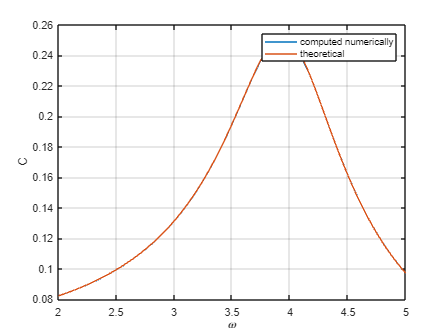

LAB06ex2

### Part (b)

Value of $\omega$ that gives the practical resonance frequency: ~ 3.9

Coresponding maximum value of the amplitude $C$: 0.25

### Part (c)

Compute analytically the value of $\omega$ that gives the practical resonance frequency by differentiating $C$: 3.9369

### Part (d)

*Run LAB06ex1 with the value of *$\omega$* found in part (c).  Here, it is convenient to create a new M-file for this problem, e.g. LAB06ex1_d.m. You should create a copy of LAB06ex1.m and then change the value of *$\omega$*.*

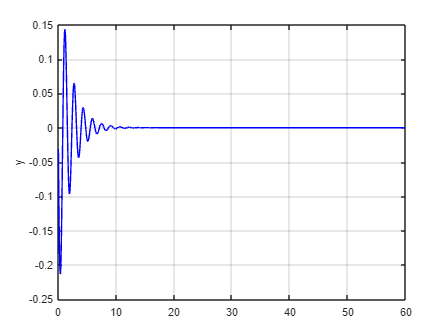

computed amplitude of forced oscillation = 0.25198
theoretical amplitude = 0.25198


LAB06ex1_d

Amplitude of the forced oscillation:

How does it compare with the amplitude of the forced oscillation found in problem 1? 

    The amplitude of the firced solution is greater than that found in problem 1.

If you run LAB06ex1.m with any other value of $\omega$, how do you expect the amplitude of the solution to be?

    I expect it to be less than the the amplitude we just found.

### Part (e)

Is the amplitude of the forced oscillation,  $C$, affected by the initial conditions?

    No, it is not.

# Exercise 3

Set $c=0$ in LAB06ex2.m and run it

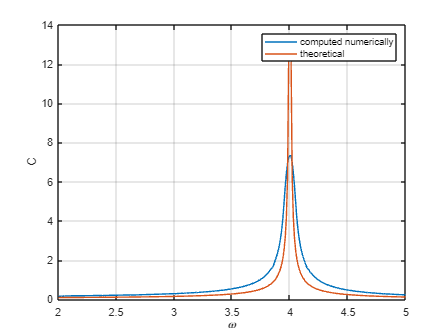

LAB6ex2_1

### Part (a)

What is the maximal amplitude? 

    The maximum amplitude is about 12.5

What is the value of $\omega$ yielding the maximal amplitude in the forced oscillation?

    The value of omega is 3.99.

How does this value compare to $\omega_0$?

    It is very close to the same, only off by 0.01.

### Part (b)

*Set *$c=0$* and *$\omega$* equal to the value found in part (a) in LAB06ex1.m  and run it. Here, it is convenient  to create a new M-file for this problem, e.g. LAB06ex3_b.m. This file will be the same as LAB06ex1.m except for the values of c and *$\omega$*.*

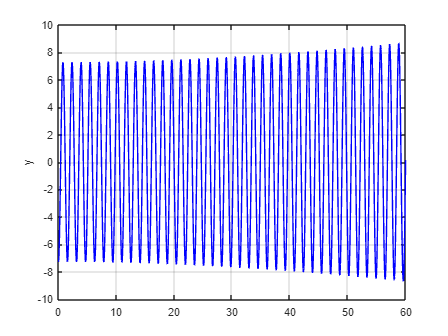

computed amplitude of forced oscillation = 7.2751
theoretical amplitude = 12.5156


LAB06ex3_b

Comment on the behavior of the solution: It grows out of control and the amplitude gets greater and greater.

# Exercise 4

*Set *$c=0$* and *$\omega $* equal to the given value in  LAB06ex1.m . Extend the interval of simulation  and run it. Here, it is convenient  to create a new M-file for this problem, e.g. LAB06ex4.m. This file will be the same as LAB06ex1.m except for the values of c , *$\omega$ *and for the value of*` tf`. * You can delete lines 10-14 in your new file as they are no longer relevant.*

type LAB06ex4.m

clear; clc; %this deletes all variables 
omega0 = 4; c = 0; omega = 3.8;
if omega0 > omega
    alpha = atan((c*omega)/(omega0.^2-omega.^2));
else
    alpha = pi + atan((c*omega)/(omega0.^2-omega.^2));
end
param = [omega0,c,omega]; 
t0 = 0; y0 = 0; v0 = 0; Y0 = [y0;v0]; tf = 80;
options = odeset('AbsTol',1e-10,'relTol',1e-10); 
[t,Y] = ode45(@f,[t0,tf],Y0,options,param);  
t1 = 25; i = find(t>t1);
C = (max(Y(i,1))-min(Y(i,1)))/2;
y = Y(:,1)-C*cos(omega*t-alpha); v = Y(:,2);
figure(6); clf;
plot(t,y,'b-'); ylabel('y'); grid on; hold on;
C=1/abs(omega0^2-omega^2);
A=2*C*cos((omega0-omega)*t/2);
plot(t,A,'r-',t,-A,'g-');

disp(['computed amplitude of forced oscillation = ', num2str(C)]);
Ctheory = 1/sqrt((omega0^2-omega^2)^2+(c*omega)^2); 
disp(['theoretical amplitude = ', num2str(Ctheory)]);
%----------------------------------------------------------------
function dYdt = f(t,Y,param) 
y = Y(1); v = Y(2); 
omega0 = param(1); c = param(2); omega = param(3);
dYdt = [ v ; cos(omega*t)-omega0

### Part (a)

Define the "envelope" functions $A$ and $-A$ in LAB06ex4.m

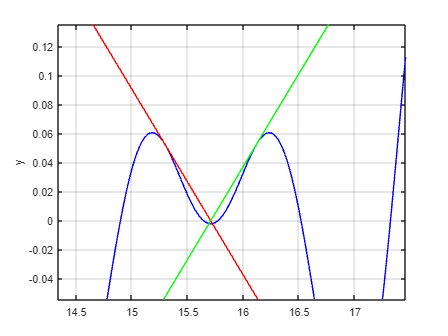

computed amplitude of forced oscillation = 0.64103
theoretical amplitude = 0.64103


LAB06ex4

### Part (b)

Period of the fast oscillation computed analytically: 1.08

### Part (c)

Length of beats: 0.0606

### Part (d)

*Change the value of *$\omega $* in LAB06ex4.m and run it (use a new M-file)*

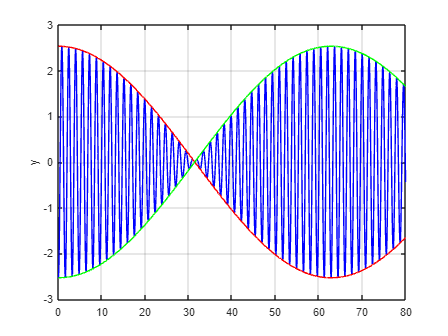

computed amplitude of forced oscillation = 1.2658
theoretical amplitude = 1.2658


LAB06ex4_d1

*Change the value of *$\omega $* in LAB06ex4.m and run it (use a new M-file)*

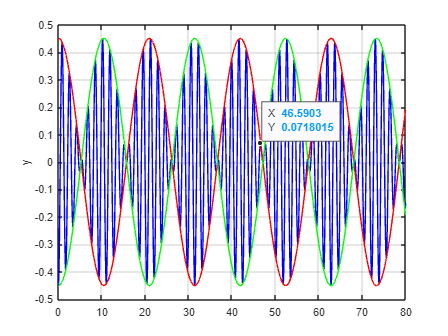

computed amplitude of forced oscillation = 0.22523
theoretical amplitude = 0.22523


LAB06ex4_d2

Period of the fast oscillation and length of beats for the two values of $\omega $: When omega is larger, the beats have a harger amplitude but a smaller period

How do the periods compare to parts (a) and (c ) ? That is, does the period increase or decrease as $\omega $ gets farter away from $\omega_0$?  Does the length of beats increase or decrease as as $\omega $ gets farter away from $\omega_0$? 

When omega is larger, the beats have a harger amplitude but a smaller period

### Part (e)

*Change the value of *$\omega $* in LAB06ex1.m (save it to a new file) and run it*

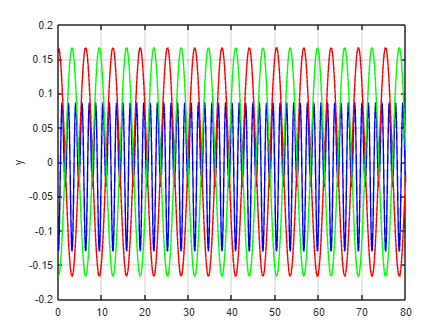

computed amplitude of forced oscillation = 0.083333
theoretical amplitude = 0.083333


LAB06ex4_e

Is the beats phenomemon still present? Why or why not? No it is not, because the difference between omega and omega0 is too large.